## Initial Conditions

### Global Variables

Coordinate system:

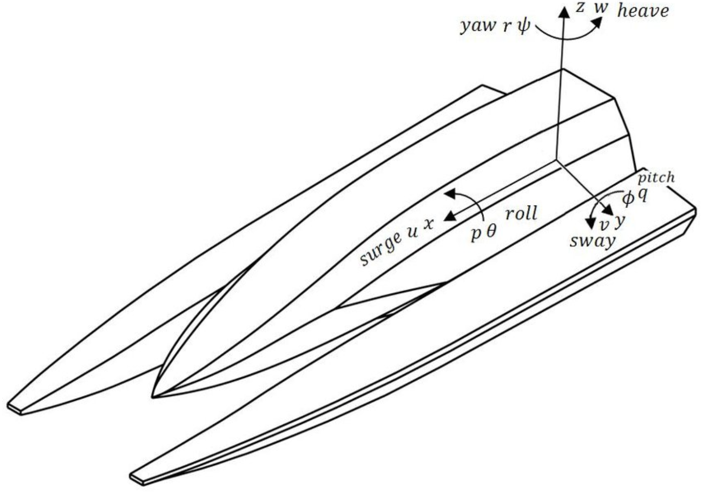

Wind always comes from the right side of the vessel, true wind angle will always be negative because as the wind "opens" from the bow, it follows the negative direction (think right hand rule).

W_speed = 0.01; % wind speed [m/s]
W_angle = 0.01; % [rad] wind angle relative to bow, (+ve to the right)

## Sample Convergence Code

clear;
W_speed = 10;
W_angle = deg2rad(-90);

initialize

difference = 1;
old_speed = 0;
old_heel = 0;
i = 1;

boat_stats = zeros(1,4);

while ( (difference > 0.001) && i < 100)

    [boat_reaction] = computeSailState(sailMedium, W_speed, W_angle, boat_reaction, boat_speed, boat_heel, S_span, S_avg_ch, S_alpha, S_mass, S_airfoil);
    [boat_reaction, boat_speed] = computeHullState(hullMedium, boat_reaction, boat_speed);
    [boat_reaction, boat_heel, at_stall] = computeKeelState(keelMedium, W_speed, W_angle, boat_reaction, boat_speed, boat_heel, K_span, K_avg_ch, K_mass, K_airfoil);
    
    speed = norm(boat_speed)*ms_to_kn;
    heel = rad2deg(boat_heel);
    difference = abs(speed-old_speed) + abs(heel-old_heel);
    old_speed = speed;
    old_heel = heel;

    boat_stats(i,1:4) = [speed heel difference at_stall];
    i = i + 1;

end
figure;
plot(boat_stats)

## Polar Plot

Interation to find boat speed based on wind speed and heading relative to wind

clear;
initialize;

W_speed_kn = [10; 15; 20]; % wind speed [kn]
W_heading_range_deg = -45:-10:-165; % heading relative to true wind [deg]
W_heading_range_deg(size(W_heading_range_deg,2)) = -179; % modify last value


% change wind speed
for w = 1:size(W_speed_kn,1)

    W_speed = W_speed_kn(w)/ms_to_kn;
    
    % change true wind angle
    for k = 1:size(W_heading_range_deg,2)

        W_angle = deg2rad(W_heading_range_deg(k));

        [boat_stats] = converge(W_speed, W_angle);
        
        speed_polar(k,w) = boat_stats(end,1);

    end
end

% plotting polar speed
figure;
color_array=['c'; 'b'; 'g'; 'y'; 'r'];
label_array=num2str(W_speed_kn);
label_array=label_array + "kn";
speed_polar_temp=transpose(speed_polar(:,1));
W_heading_range_rad=deg2rad(W_heading_range_deg);
polarplot(W_heading_range_rad, speed_polar_temp, color_array(1))
title('Hull Speed [kn] @ Hull Headings [deg] and Wind Speeds [kn]');

text(W_heading_range_deg(1), speed_polar(1,1),label_array(1,:));
hold on;
for w = 2:size(speed_polar,2)
    speed_polar_temp=transpose(speed_polar(:,w));
    polarplot(W_heading_range_rad,speed_polar_temp,color_array(w))
    text(W_heading_range_deg(1),speed_polar(1,w),label_array(w,:));
end
maximum = max(max(speed_polar_temp));
[x,y]=find(speed_polar==maximum);
fprintf('Optimal Sailing Heading: %g deg',W_heading_range_deg(1,x))

## Where is the worst heel angle?

Iterating through headdings to find worst heeling angle, at highwst wind speed

initialize

W_speed = W_speed_kn(5)/ms_to_kn;

for k = 1:size(W_heading_range_deg,2)

    W_angle = deg2rad(W_heading_range_deg(2));

    difference = 1;
    old_boat_speed = 0;
    i = 1;
    boat_stats = zeros(1,2);
    
    while (difference > 0.0001)
    
        [boat_reaction] = computeSailState(sailMedium, W_speed, W_angle, boat_reaction, boat_speed, boat_heel, S_span, S_avg_ch, S_alpha, S_mass, S_airfoil);
        [boat_reaction, boat_speed] = hull(boat_reaction, H_par);
        [boat_reaction, boat_heel] = computeKeelState(keelMedium, W_speed, W_angle, boat_reaction, boat_speed, boat_heel, K_span, K_avg_ch, K_mass, K_airfoil);
        
        difference = abs(boat_heel-old_boat_speed);
        old_boat_speed = boat_heel;
    
        boat_stats(i,1:2) = [boat_speed rad2deg(boat_heel)];
        i = i + 1;
    
    end

    boat_heel_at_heading(k) = boat_heel;

end

% plotting heel angle
figure;
hold on;
plot(W_heading_range_deg, boat_heel_at_heading)
yline(20);
yline(-20);
title('Finding Worst Heeling angle @ Hull Heading')
xlabel('Hull heading relative to true Wind [deg]')
ylabel('Hull Heel Angle [deg] (port=+ve)')

## Keel Study - Length

Here we investigate the variance of keel parameters on the performance. We choose a heading of 126deg (20deg of heel in the previous plot), and max wind speed (20kn)

% modifying keel values
var_factor = 0.25;
K_weightArr = (K_weight-K_weight*0.1):20:(K_weight+K_weight*0.1)
K_lengthArr = (K_length-K_length*var_factor):0.01:(K_length+K_length*var_factor);
% setting environmental const
W_speed = W_speed_kn(5)/1.94384;
H_heading=deg2rad(100);

for j = 1:size(K_weightArr,2)
    for k = 1:size(K_lengthArr,2)
        S_area_M=S_area;
        difference=1;
        while (difference > 0.0001) 
            % Compute
            [boat_heading] = getApparentWind(W_speed, boat_speed, H_heading);
            [S_thrust,S_torque, sail_heeling_force_wind,S_angle]=sail(rho_air, mu_air, naca18, W_speed, boat_heading, S_area_M, S_avg_ch, S_alpha, S_span, S_mass, boat_heel_rad);
            [boat_heel_rad]=keel(S_torque, K_length, K_weight, sail_heeling_force_wind, boat_heel_rad);
            [boat_speed]=hull(S_thrust, H_par);
            
            % Rectify Area
            old_S_area_M=S_area_M;
            S_area_M=S_area*cos(boat_heel_rad);
    
            % difference
            difference=abs(old_S_area_M-S_area_M);
        end
        H_speeds_at_keel(j,k)=boat_speed*ms_to_kn;
        H_heel_deg_at_keel(j,k)=rad2deg(boat_heel_rad);
    end 
end

figure;
% find half of domain
half_of_x_domain=fix(size(K_lengthArr,2)/2);
yyaxis left
plot(K_lengthArr, H_speeds_at_keel(1,:));
ylabel('Hull Speed [kn]')
text(K_lengthArr(1,half_of_x_domain),H_speeds_at_keel(1,half_of_x_domain),'\leftarrow' + string(K_weightArr(1)) + 'Kg')
yyaxis right
plot(K_lengthArr, H_heel_deg_at_keel(1,:));
ylabel('Hull Heel Angle [deg]')
title('Keel Study')
xlabel('Keel Length [m]')
hold on
for w = 2:size(H_speeds_at_keel,1)
    yyaxis left
    plot(K_lengthArr, H_speeds_at_keel(w,:));
    text(K_lengthArr(1,half_of_x_domain),H_speeds_at_keel(w,half_of_x_domain),'\leftarrow' + string(K_weightArr(w)) + 'Kg')
    yyaxis right
    plot(K_lengthArr, H_heel_deg_at_keel(w,:));
end
hold off

## Print Variables

fprintf(...
    'Sail angle of attack: %g deg',S_alpha,...
    'Sail area: %g m2',S_area,...
    'Sail mass: %g kg',S_mass,...
    'Hull Max Speed: %g kn',boat_max_speed_kn,...
    'Keel weight: %g kg',K_weight,...
    'Keel length: %g m',K_length...
    )